## 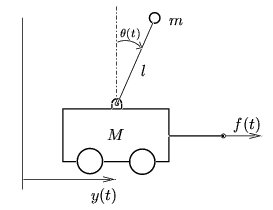


$$\vec{y} = \pmatrix{y \cr  \theta \cr \dot{y} \cr \dot{\theta}}$$


**Load cartPend Non Linear Function**

clearvars, clc;

f = load('cartPend_Dynamics_incl_damping.mat');
cartPend = f.f;
clearvars('f');

**Simulate**

iCond = [0.0; pi/8; 0.0; 0.0];
tInit = 0;
tFinal = 10;
tSpan = [tInit:0.01:tFinal]';



F_val = 0.0;
M_val = 5.0;
g_val = 10.0;
d_val = 100.0;
l_val = 2.0;
m_val = 1.0;
% extraParamsVals = [F_val M_val g_val l_val m_val];

opt = odeset('RelTol',10.0^(-7), 'AbsTol',10.0^(-7));
sol = ode45(@(t, y) cartPend(t, y, [F_val M_val d_val g_val l_val m_val]), tSpan, iCond, opt);

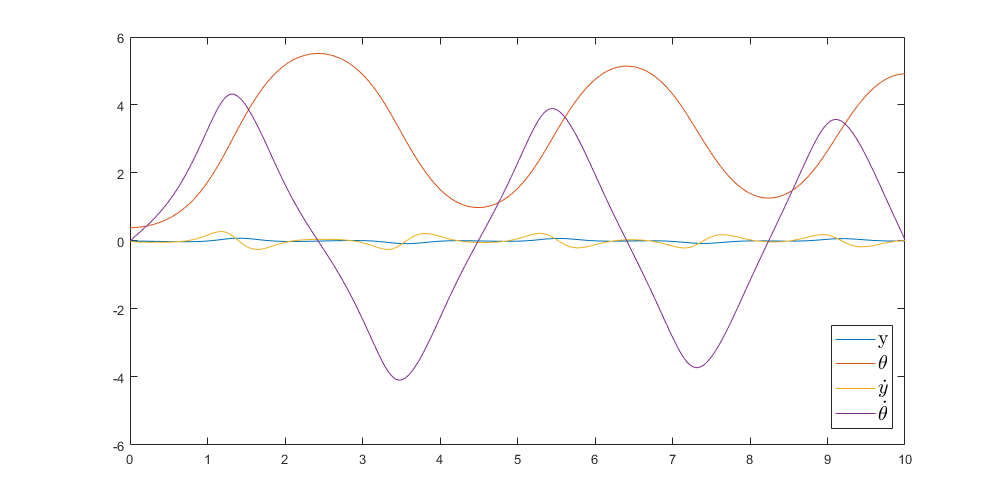

figure("Position",[0 0 1000 500])
plot(sol.x, sol.y)
legend({'y', '$\theta$', '$\dot{y}$', '$\dot{\theta}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15)

% run('cartPendAnimation_aux.m')